# **Non-Standard Finite Difference numerical scheme for the age-of-infection epidemic model**

## Credits & Project Information

This Live Script was developed as part of the project **EPITIME: *****A Computational Framework for Integral Epidemic Models with Structure-Preserving Discretizations*****.**

The complete source code and further documentation are available at the following repository: [https://github.com/ghitan/EPITIME](https://github.com/ghitan/EPITIME) .

**Authors & Contributors**

- [**M. Pezzella**](https://orcid.org/0000-0002-1869-945X) — IAC-CNR, Naples, Italy

- [**C. Panico**](https://orcid.org/0009-0007-4390-1449)**, **[**E. Messina**](https://orcid.org/0000-0003-4545-6266)**, **[**B. Buonomo**](https://orcid.org/0000-0003-4998-3725) — University of Naples Federico II, Naples, Italy

- [**G. Zanghirati**](https://orcid.org/0000-0002-5282-9158) — University of Ferrara, Italy

If you use this tool in your research, please cite the project and the related papers appropriately (see [https://arxiv.org/abs/2605.00067v1](https://arxiv.org/abs/2605.00067v1))

**Version**

1.0 - Date: April 2026

**License**

This software is distributed under the GNU GPL v.3. Please see the repository or [https://www.gnu.org/licenses](https://www.gnu.org/licenses) for all details.

## **1. The model**

Here, we address the integro-differential equation representing the Kermack and McKendrick ***Age-of-Infection (AoI)*** epidemic model 

                            $\displaystyle S^{\prime}(t)=\beta_0 S(t)\int_{0}^{\infty}[S^{\prime}(t-\tau)]A(\tau)\ d\tau,$                                                               **(1)** 

where $S(t)$ is is the number of susceptibles at time $t$, $\beta_0$ represents the rate of effective contacts and $A(\tau)=\pi(\tau)B(\tau)$ is the  mean infectivity of members of the population with infection age $\tau$. More specifically, given a closed population of size $N,$ we are interested in providing a simulation method for the following equivalent reformulation of **(1)**

                            $S^{\prime}(t)=-\beta_0 S(t)\varphi(t), \\
\varphi(t)=\varphi_0(t)+ \beta_0 \int_{0}^{t}A(t-\tau) S(\tau)\varphi(\tau) \ d\tau,$                                                         **(2)**

where  $\varphi(t)=-\int_{0}^{+\infty}{A(\tau)S^{\prime}(t-\tau) \ d\tau ,$  represents the total infectivity of individuals at time $t$ and  $\varphi_0(t)=-\int_{t}^{\infty}A(\tau)S^{\prime}(t-\tau) \ d\tau\leq (N-S(0))A(t)$ is the total infectivity of members of the population who were infected at the intial outbreak $t=0$. 

We refer to **[3]**, **[4]** and references therein for a detailed description and analysis of AoI epidemic models of the form **(1)** and **(2)**.

## **2. The NSFD Scheme**

The present code is based on the ***Non-Standard Finite Difference (NSFD)*** method proposed in **[7]**. Let $t_n=nh,$ where $n=0,1,\dots,$ denote a uniform mesh with stepsize $h>0.$ The NSFD scheme then reads

                                $S_{n+1}=S_n-h \beta_0 S_{n+1}\varphi_n \\
\varphi_{n+1}=\varphi_0(t_{n+1})+h \beta_0\sum_{j=0}^{n} A(t_{n+1-j})S_{j+1}\varphi_j,$                                              **(3)**

for $n=0,1,\ldots,$ where $S_0=S(0)>0,$  $\varphi_0=\varphi_0(0)\geq0,$ and  $S_n\approx S(t_n),$  $\varphi_n\approx \varphi(t_n)$. 

A rigorous theoretical analysis of the numerical properties and of the dynamical consistency of the method **(3)** is provided in **[7]**]. We briefly summarize the principal outcomes:

- The NSFD scheme **(3)** is consistent and convergent of order 1. Hence, the approximation error $$e(h;t_n) = \left\| \left[ \begin{array}{c} S(t_n) \\ \varphi(t_n) \end{array} \right] -
\left[ \begin{array}{c} S_n \\ \varphi_n \end{array} \right] \right\|$
$vanishes linearly with $h.$

- The method **(3)** is unconditionally non-negative. More specifically, independently of $h>0,$ $S_n>0$ and $\varphi_n\geq0,$ for all $n \in \mathbb{N}.$ Furthermore, the NSFD solution is coherently bounded since $0<S_\infty<S_n<S_0$ and $0\leq\varphi_n\leq N\sup_{t\geq0}A(t),$ for all $n \in \mathbb{N}.$

- The discretization **(3)** is monotonicity-preserving since, for any $h>0,$ the sequence $\{S_n\}_{n \in \mathbb{N}}$ is  non-increasing.  Consequently, the limit $S_\infty(h)=\lim_{n\to \infty} S_n,$  exists and is referred to as the **numerical final size**.

- Let $R_0(h)=h \beta_0 N\sum_{n=0}^{+\infty}A(t_{n+1})$ denote the **numerical basic reproduction number.  **A discrete *invasion criterior* holds true, i.e. the NSFD solution initially grows exponentially as $(1+rh)^n$ with $r>0$ iff $R_0(h)>1.$

- The numerical final size satisfies $\lim\limits_{h\to 0}\left(\log\left({\frac{S_0}{S_\infty(h)} }\right)-h \beta_0(N-S_\infty(h))\sum_{n=0}^{\infty}A(t_{n+1}) \right)=0,$ which is a direct discrete counterpart of the continuous-time final size relation (cf. **[1]****)**. 

## 3. Some Numerical Experiments

⚠️` Warning`: The simulations require `NSFD_AoI.m` which implements the scheme **(3)**. Please ensure that this file is available in MATLAB's path before running this section.

clearvars; clc; close all;
if exist('NSFD_AoI.m','file') ~= 2
    error(['⚠️ The required file NSFD_AoI.m was not found. ', ...
        'Please make sure it is in the current folder or in MATLAB path.']);
else
    disp('✅ NSFD_AoI.m found. You can safely run the simulations below.');
    disp('🔍 To open the file, type: edit(''NSFD_AoI.m'')');
end

✅ NSFD_AoI.m found. You can safely run the simulations below.


🔍 To open the file, type: edit('NSFD_AoI.m')


💡 For a more immediate and interactive experience, it is recommended to switch to the *code-hidden view*, which can be selected from the *View* tab in MATLAB.

### 3.1 A Simulation Tool

In this section, we provide a streamlined and user-friendly tool, implemented as an intuitive GUI, to facilitate the simulation of the model **(2)**. Specifically, a form has been designed that allows the user to directly input the desired parameters for the simulation. If any field is left empty, the corresponding default value will automatically be applied (for further details, refer to the code `NSFD_AOI.m`). The simulation is then performed using the NSFD method **(3)** originally introduced in **[7]**.

**Please enter all the parameters directly. **

⚠️` Warning`: Only ensure that $A(t)$ and $\varphi_0(t)$ are defined in vectorized form, using component-wise operators and $t$ as the independent variable. For instance, write `t.*exp(-t.^2)./(1+t.^3)` for the function $\frac{te^{-t^2}}{1+t^3}$.

input = struct();
input.N = "";        input.S0 = "";
input.beta = "";     input.T = "5";
input.A ="10./(1+t.^5)";         input.phi0 = ""; 
input.h = ""; 
fn = fieldnames(input);
AoI_Problem = struct();
for k = 1:numel(fn)
    val = input.(fn{k});
    if strlength(val) > 0
        if strcmp(fn{k}, 'A') || strcmp(fn{k}, 'phi0')
            val
            AoI_Problem.(fn{k}) = str2func(['@(t)',char(val)]);
        else
            AoI_Problem.(fn{k}) = str2double(val);
        end
    end
end

val = "10./(1+t.^5)"

AoI_Problem.verbosity = 1;
disp('The following input parameters have been successfully acquired:')

The following input parameters have been successfully acquired:


disp(AoI_Problem)

            T: 5
            A: @(t)10./(1+t.^5)
    verbosity: 1



[t_AoI,Y_AoI,P_AoI] = NSFD_AoI(AoI_Problem);

disp(['The simulation has been successfully completed, and the results have been stored in the variables t_AoI and Y_AoI.' newline 'A summary of the performance indicators is available in the variable P_AoI.'])

The simulation has been successfully completed, and the results have been stored in the variables t_AoI and Y_AoI.
A summary of the performance indicators is available in the variable P_AoI.


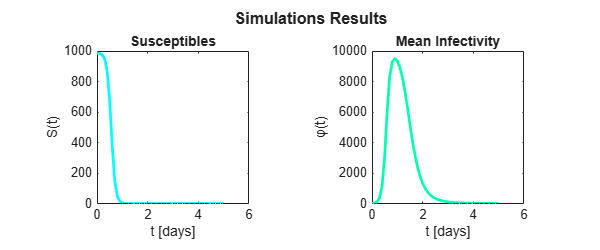

set(groot, "defaultFigureMenuBar", "figure");           set(groot, "defaultFigureToolbar", "figure");
figure('Position',[100 100 600 250]);
tiledlayout(1,2);
nexttile
plot(t_AoI, Y_AoI(1,:),'c','LineWidth',2);
xlabel('t [days]'); ylabel('S(t)'); axis square
title('Susceptibles')
nexttile
plot(t_AoI, Y_AoI(2,:),'Color',[0.00,1.00,0.70],'LineWidth',2); hold on
xlabel('t [days]'); ylabel('φ(t)'); axis square 
title('Mean Infectivity')
sgtitle('Simulations Results','FontSize',12,'FontWeight','bold');

### 3.2 Convergence Tests

In the following tests, we provide experimental evidence of the linear convergence of the NSFD method **(3)****.** Different illustrative choices for the infectivity kernel function $A(t)$ are considered. The resulting **mean **$L_2$**-norm errors** and the corresponding **experimental rates of convergence **$\rho(h)$, defined as


$$E_2(h)=\frac{1}{N_t}\sum_{n=0}^{N_t}  \frac{\left\|\left[\begin{array}{c} \mathcal{S}_n \\ \mathcal{\Phi}_n \end{array} \right] -
\left[ \begin{array}{c} S_n \\ \varphi_n \end{array}\right]\right\|_2}{
 \left\|\left[\begin{array}{c} \mathcal{S}_n \\ \mathcal{\Phi}_n \end{array} \right]\right\|_2}, \qquad \qquad \rho(h)=\log_2\left(\frac{E_2(h)}{E_2(0.5h)}\right),

 
$$


are reported. The reference solution $\left[\begin{array}{c} \mathcal{S}_n \\ \mathcal{\Phi}_n \end{array} \right]$ is computed using the same NSFD method **(3)** with a sufficiently small stepsize $h_{ref}$.

**Please select one function from the drop-down menu below.**

ORD_Problem = struct();
h_ref = 2^(-13);
ORD_Problem.T = 2;      ORD_Problem.h = h_ref;
ORD_Problem.N = 1e4;    ORD_Problem.beta = 1e-4;
ORD_Problem.S0 = 0.9*ORD_Problem.N;
ORD_Problem.A = @(t) sin(5*pi*t).^2; 
ORD_Problem.phi0 = @(t)( (ORD_Problem.N - ORD_Problem.S0) * ORD_Problem.A(t) );
ORD_Problem.verbosity = 1;

[t_ref,Y_ref,P_ref] = NSFD_AoI(ORD_Problem);
TestN = -log2(h_ref)-2;
H = zeros(TestN,1);     Err = zeros(TestN, 1);
for j = 1:TestN
    h_test = 2^(-j);
    H(j) = h_test;
    AoI_problem_test = ORD_Problem;            AoI_problem_test.h = h_test;
    [~,Y_test,~] = NSFD_AoI(AoI_problem_test);
    zooming = 1:h_test/h_ref:size(Y_ref,2);
    Err(j)=mean(vecnorm(Y_ref(:,zooming)-Y_test,2)./vecnorm(Y_test,2));
end
OrderErr = log2(Err(1:end-1) ./ Err(2:end));
OrderErr = [0; OrderErr];
format short
T_Ord = table(-(1:TestN)', Err(:), round(OrderErr(:),2), ...
    'VariableNames', {'log₂(h)', 'Rel. Error E₂(h)', 'Order ρ(h)'});
disp(T_Ord)

    log₂(h)    Rel. Error E₂(h)    Order ρ(h)
    _______    ________________    __________

       -1           0.022712             0   
       -2           0.012135           0.9   
       -3          0.0058774          1.05   
       -4          0.0026415          1.15   
       -5          0.0013285          0.99   
       -6         0.00066525             1   
       -7         0.00033093          1.01   
       -8         0.00016307          1.02   
       -9         7.8963e-05          1.05   
      -10         3.6862e-05           1.1   
      -11         1.5801e-05          1.22   



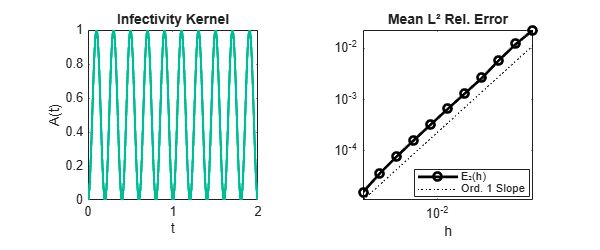


figure('Position',[100 100 600 250]);
tiledlayout(1,2);
nexttile
plot(t_ref,ORD_Problem.A(t_ref),'Color',[0.00,0.74,0.59],'LineWidth',2)
xlabel('t'); ylabel('A(t)'); axis square; title('Infectivity Kernel') 
nexttile
loglog(H,Err,'o-k','LineWidth',2); hold on 
shift=0.5*Err(1)/H(1); loglog(H,shift*H,':k'); 
xlabel('h'); axis square tight;   
title('Mean L² Rel. Error'); legend('E₂(h)','Ord. 1 Slope','Location','best');

### 3.3 Analysis of the Influenza Outbreak at an English Boarding School

The AoI framework **(2)** is general enough to encompass well-established compartmental differential models. For instance, as discussed in **[2]** and [8], the **Susceptible–Infective–Recovered (SIR) model** can be derived from **(2)** by assuming that the infectious period follows an exponential distribution with parameter $\gamma$, which is equivalent to assuming that each infective has a constant probability $\gamma$ per unit time of moving to the removed compartment (i.e., becoming recovered and immune). In this settng, assuming that all initial infective have infection-age zero at $t=0,$ we have

$A(t)=e^{-\gamma t},  \quad \pi(t)=1, \qquad B(t)=A(t), \quad \varphi_0(t)=(N-S_0)A(t), \quad I(t)=\varphi(t), \quad R(t)=N-S(t)-\varphi(t)$.

Here, we apply the AoI model **(2)** to simulate the influenza epidemic that occurred in a boarding school in northern England during January–February 1978. The school housed a total of $N=763$ boys, all of whom were at risk during the epidemic. At its onset, on January 22, three boys were already ill. The dataset considered here corresponds to that reported in **[6, Section 2.2.2]**, and the table below gives the number of boys who were sick on the n-th day after January 22.

format short
Day =[0 3:14];
Infected_Data = [3 25 75 227 296 258 236 192 126 71 28 11 7];
startDate = datetime(1978,1,22);
dates = startDate + days(Day);    dates.Format = 'ddMMM';
T = array2table([Day; Infected_Data], ...
    'RowNames', {'Day','Infected'}, ...
    'VariableNames', cellstr(dates));

disp(T)

                22Jan    25Jan    26Jan    27Jan    28Jan    29Jan    30Jan    31Jan    01Feb    02Feb    03Feb    04Feb    05Feb
                _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____

    Day           0        3        4         5        6        7        8        9       10      11       12       13       14  
    Infected      3       25       75       227      296      258      236      192      126      71       28       11        7  



In **[6, Section 6.2.1]** the parameters $\beta_0$ and $\gamma$ of the SIR model are estimated from the data, with 95% confidence intervals of [0.0022099, 0.00254] and [0.4257, 0.5037], respectively. In the following, we explore the effect of varying these parameters within the specified intervals, and we present the corresponding simulations obtained using the NSFD scheme **(3)** proposed in **[7]**.

**Please use the following sliders to change the parameters.**

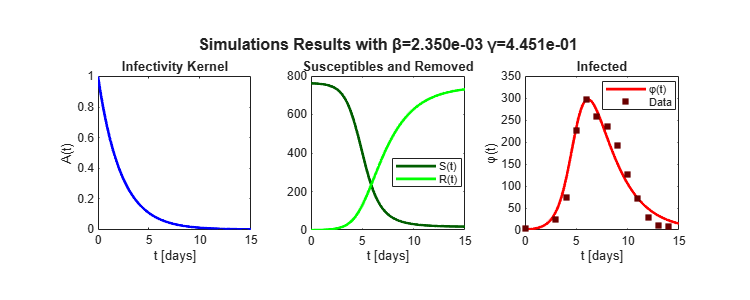

format short e
beta =0.0023499;   gamma = 0.4451;
SIR_Problem = struct();
SIR_Problem.T = 15;        SIR_Problem.h = 5e-2;
SIR_Problem.N = 763;       SIR_Problem.S0 = 762;
SIR_Problem.beta = beta;   SIR_Problem.verbosity = 0;
SIR_Problem.A = @(t)( exp(-gamma*t) );
SIR_Problem.phi0 = @(t)( (SIR_Problem.N - SIR_Problem.S0) * SIR_Problem.A(t) );
[t_SIR, Y_SIR, P_SIR] = NSFD_AoI(SIR_Problem);
figure('Position',[100 100 750 300]); tiledlayout(1,3);
nexttile
plot(t_SIR, SIR_Problem.A(t_SIR),'b','LineWidth',2);
xlabel('t [days]'); ylabel('A(t)'); title('Infectivity Kernel'); axis square
nexttile
plot(t_SIR, Y_SIR(1,:),'Color',[0.00,0.37,0.00],'LineWidth',2); hold on
plot(t_SIR, SIR_Problem.N-sum(Y_SIR,1),'g','LineWidth',2);
xlabel('t [days]'); legend('S(t)', 'R(t)','Location','best'); axis square
title('Susceptibles and Removed')
nexttile
plot(t_SIR, Y_SIR(2,:),'r','LineWidth',2); hold on
scatter(Day, Infected_Data, 's', 'filled', 'MarkerFaceColor', [0.42 0 0])
xlabel('t [days]'); ylabel('φ(t)'); axis square
title('Infected'); ylim([0 350]); legend('φ(t)','Data','Location','best')
sgtitle(sprintf('Simulations Results with β=%.3e γ=%.3e', SIR_Problem.beta, gamma),'FontSize',12,'FontWeight','bold');

### 3.4 An Inverse Problem Framework for Inferring COVID-19 Infectivity Kernel

Despite the modeling potential of the integrodifferential formulation **(2)**, the identification of a kernel infectivity function $A(t)$ that faithfully reflects a real epidemic scenario remains a demanding task. Here, we introduce a functional optimization procedure specifically devised to tackle this problem. In particular, we make use of incidence data from *Il Sole 24 Ore* ([**https://lab24.ilsole24ore.com/coronavirus**](https://lab24.ilsole24ore.com/coronavirus)**) **and demographic data from ISTAT ([**https://esploradati.istat.it**](https://esploradati.istat.it/databrowser/#/it/dw/categories/IT1,POP,1.0/POP_POPULATION/DCIS_POPRES1/IT1,22_289_DF_DCIS_POPRES1_1,1.0)** ).**

CSVfname = 'Italy-daily-trend.csv';
if exist(CSVfname,'file') ~= 2
    error(['⚠️ The required file NSFD_AoI.m was not found. ', ...
        'Please make sure it is in the current folder or in MATLAB path.']);
else
    disp(['✅ ',CSVfname,' found. You can safely run the simulations below.']);
    disp(['🔍 To open the file, type: open(''',CSVfname,''')']);
end

✅ Italy-daily-trend.csv found. You can safely run the simulations below.


🔍 To open the file, type: open('Italy-daily-trend.csv')


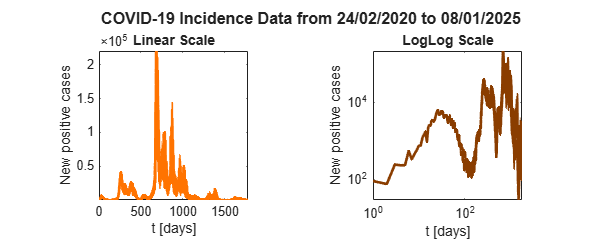

Table_Covid = readtable(CSVfname);
Table_Covid.data = datetime(Table_Covid.data,'InputFormat','dd/MM/yyyy');
t_data_covid = days(Table_Covid.data - Table_Covid.data(1));
Incidence_data_covid = Table_Covid.nuovi_positivi;  Norm_factor = max(Incidence_data_covid);
Incidence_data_covid_norm = Incidence_data_covid/Norm_factor;
Table_Covid.data.Format = 'dd/MM/yyyy';
figure('Position',[100 100 600 250]);
tiledlayout(1,2);
nexttile
plot(t_data_covid, Incidence_data_covid, 'Color', [1.00,0.45,0.00], 'LineWidth',2)
xlabel('t [days]'); ylabel('New positive cases'); title('Linear Scale'); axis square tight
nexttile
loglog(t_data_covid, Incidence_data_covid, 'Color', [0.54,0.24,0.00], 'LineWidth',2)
title('LogLog Scale'); xlabel('t [days]'); ylabel('New positive cases'); axis square tight
sgtitle("COVID-19 Incidence Data from " + string(Table_Covid.data(1)) + ...
      " to " + string(Table_Covid.data(end)),'FontSize',12,'FontWeight','bold')

As a preliminary step, the incidence data, defined as the number of newly reported daily cases, are smoothed via locally weighted linear regression and subsequently normalized by division through their maximum value $I_{\max}$, so as to lie within the interval $[0,1]$. Through this procedure, we obtain the daily values of the normalized and smoothed incidence $\mathcal{I}_i^{\text{data}}$, evaluated at the time points $t^{\text{data}}_i$ for $i=0,\dots,N_{\text{data}}$. These data will then be compared with the simulated normalized incidence values, which, according to the first equation in **(2)**, take the form $\mathcal{I}(t)=\beta I_{\max}^{-1} \ S(t)\,\varphi(t)$.

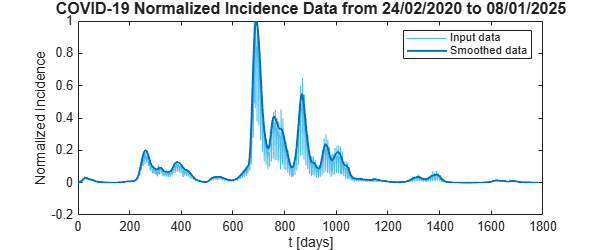

incidence_smoothed_data = smoothdata(Incidence_data_covid,...
    "loess","SmoothingFactor",0.25,"SamplePoints",t_data_covid);
Norm_factor = max(incidence_smoothed_data);
incidence_norm_smoothed_data = incidence_smoothed_data./Norm_factor ;
figure('Position',[100 100 600 250]);
plot(t_data_covid,Incidence_data_covid_norm,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(t_data_covid,incidence_norm_smoothed_data,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend('Input data','Smoothed data'); xlabel('t [days]'); ylabel('Normalized Incidence');
title("COVID-19 Normalized Incidence Data from " + string(Table_Covid.data(1)) + ...
      " to " + string(Table_Covid.data(end)),'FontSize',12,'FontWeight','bold')

To address the problem of determining a positve infectivity function that minimizes an appropriate distance between the observed data and the simulation outcomes, we first propose an expansion of the kernel in terms of Bernstein basis polynomials **[5]**, expressed as follows


$$A(t)=\sum_{n=0}^{N_{\text{pol}}-1} \kappa_n  B_{n,N_{\text{pol}}-1}\left(\frac{t}{T}\right)=\sum_{n=0}^{N_{\text{pol}}-1} \kappa_n \binom{N_{\text{pol}}-1}{n} \left( \frac{t}{T} \right)^{n} \left( 1 - \frac{t}{T} \right)^{N_{\text{pol}}-1 - n},  \quad  \quad t\in[0,T], \quad \text{with} \ T=\max_it_i^{\text{data}}.$$


Owing to the non-negativity of the chosen basis, the positivity of $A(t)$ is guaranteed provided that the coefficients $\kappa_n$ are non-negative. More specifically, we devise the following constrained optimization problem,


$$\begin{array}{l}
\mathbf{x}^* =
\left[\beta^*, \kappa_0^*, \kappa_1^*, \dots, \kappa^*_{N_{\text{pol}}-1}
\right]^{𝖳} = \displaystyle &\underset{\mathbf{x} \in \mathbb{R}_+^{N_{\text{pol}}+1}}{\text{argmin}} \left( w_{\text{L}^2} \sum_{i=0}^{N_{\text{data}}} \frac{(\mathcal{I}_i - \mathcal{I}(\mathbf{x}; t_i^{\text{data}}))^2}{N_{\text{data}}+1} 
+ w_{\text{peak}} (\mathcal{I}_{i_{\text{peak}}} - \mathcal{I}(\mathbf{x}; t_{i_{\text{peak}}}^{\text{data}}))^2 
+ w_{\text{initial}} (\mathcal{I}_0 - \mathcal{I}(\mathbf{x}; t_0^{\text{data}}))^2 
+ w_{\text{year}} \sum_{i=0}^{364} \frac{(\mathcal{I}_i - \mathcal{I}(\mathbf{x}; t_i^{\text{data}}))^2}{365}\right),
\\
&\text{subject to } 5\cdot10^{-10}\leq  \frac{ \beta N T}{N_{\text{pol}}} \sum_{n=0}^{N_{\text{pol}-1}}\kappa_n  \leq 50,
\end{array}
$$
 

whose objective functional corresponds to a weighted sum of several contributions, detailed as follows

- **Mean squared error over all data points:** penalizes the mean squared deviation between the observed and simulated incidences;

- **Peak squared error:** penalizes the squared difference at the time of the observed peak;

- **Initial error:** penalizes the squared difference at the first time point;

- **Yearly error:** penalizes the average squared deviation over the first 365 days of data.

The weights $w_j$ for $j \in \{\text{L}^{2}, \text{peak, initial, year}\}$ have been determined using a **reciprocal-optimum weighting approach**: each weight is set equal to the reciprocal of the optimal value of the objective functional obtained by considering only the corresponding term, i.e., setting all other weights to zero. This ensures that each contribution is appropriately balanced in the overall functional.

Futhermore, the optimization problem is subject to the additional constraint $5\cdot10^{-10}\leq  \hat\mathcal{R}_0(\mathbf{x}) \leq 50$ which enforces that the simulated basic reproduction number $\hat\mathcal{R}_0(\mathbf{x})$, defined as

$\hat\mathcal{R}_0(\mathbf{x})=: \frac{ \beta N T}{N_{\text{pol}}} \sum_{n=0}^{N_{\text{pol}-1}}\kappa_n =\beta N \int_{0}^{T}A(\tau) d \tau \leq R_0$,

remains within the chosen interval. This bound is motivated by epidemiological considerations and may be tightened in the presence of further reliable information on the exact value of the basic reproduction number $R_0=\beta N \int_0^{+\infty}\! A(\tau) \,d\tau$.

Covid_Problem = struct();
Covid_Problem.N = 58934177;
Covid_Problem.h = min(diff(t_data_covid))/4; 
Covid_Problem.T = t_data_covid(end);
Covid_Problem.S0 = 0.99*Covid_Problem.N;
Covid_Problem.verbosity = 0;
R0_COVID_ub=50; R0_COVID_lb=5e-10;
if exist('Calibration_Output.mat','file') ~= 2
    warning(['⚠️ The file Calibration_Output.m was not found. ', ...
        'Hence, the calibration procedure is going to be initiated.']);
    N_pol = 500;      NT = Covid_Problem.N*Covid_Problem.T; 
    beta_lb = sqrt(R0_COVID_lb/NT);  beta_ub = sqrt(R0_COVID_ub/NT);  
    L_lb = beta_lb*ones(1,N_pol); L_ub =beta_ub*ones(1,N_pol);
    L0 = max(L_lb) + (min(L_ub)-max(L_lb)).*rand(1,N_pol);
    beta_0 = (R0_COVID_ub/beta_ub+R0_COVID_lb/beta_lb)/(NT * 2);

% Create optimization variables

✅ Calibration_Output.mat found. The results will be loaded.


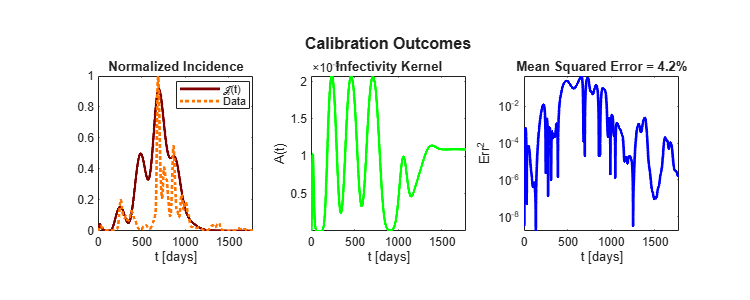

beta_CVD2 = optimvar("beta_CVD","LowerBound",beta_lb,"UpperBound",beta_ub);
Lin_Coeff_Bern2 = optimvar("Lin_Coeff_Bern",N_pol,"LowerBound",L_lb,...
    "UpperBound",L_ub);

% Set initial starting point for the solver
initialPoint.beta_CVD = beta_0;
initialPoint.Lin_Coeff_Bern = L0;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@objectiveFcn,beta_CVD2,Lin_Coeff_Bern2,...
    Covid_Problem,incidence_norm_smoothed_data,N_pol,Norm_factor);


% Define problem constraints
problem.Constraints = constraintFcn(beta_CVD2,Lin_Coeff_Bern2,Covid_Problem,...
    N_pol,R0_COVID_ub,R0_COVID_lb);

% Set nondefault solver options
options = optimoptions("fmincon","ConstraintTolerance",1e-16,"Display",...
    "iter","EnableFeasibilityMode",true,"MaxFunctionEvaluations",1000000,...
    "MaxIterations",10000,"OptimalityTolerance",1e-14,"StepTolerance",1e-14,...
    "UseParallel",true);

% Display problem information
show(problem);

% Solve problem
[Opt_Results_Covid,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","fmincon","Options",options);

% Display results
Opt_Results_Covid
reasonSolverStopped
objectiveValue

% Clear variables
clearvars beta_CVD2 Lin_Coeff_Bern2 initialPoint options reasonSolverStopped...
    objectiveValue
    Covid_ProblemOPT = Covid_Problem;
    Covid_ProblemOPT.beta = Opt_Results_Covid.beta_CVD;
    coeff_OPT = Opt_Results_Covid.Lin_Coeff_Bern(:);
    Covid_ProblemOPT.A = @(t)( bernsteinMatrix(N_pol-1, t/Covid_Problem.T) * coeff_OPT );
    Covid_ProblemOPT.phi0 = @(t)( (Covid_ProblemOPT.N - Covid_ProblemOPT.S0) * Covid_ProblemOPT.A(t) );
    [t_Covid_OPT, Y_Covid_OPT, ~] = NSFD_AOI(Covid_ProblemOPT);
    Incidence_covidOPT = Covid_ProblemOPT.beta * Y_Covid_OPT(1,:) .* Y_Covid_OPT(2,:);
    Incidence_covidOPT = Incidence_covidOPT / Norm_factor;
    SE_covid = (Incidence_covidOPT(1:4:end) - incidence_norm_smoothed_data').^2;
    MSE_covid = mean(SE_covid);
    save('Calibration_Output.mat')
else
    disp('✅ Calibration_Output.mat found. The results will be loaded.');
    warning('off')
    load('Calibration_Output.mat')
    warning('on')
end
figure('Position',[100 100 750 300]); tiledlayout(1,3);
nexttile
plot(t_Covid_OPT,Incidence_covidOPT, 'Color', [0.50, 0.00, 0.00], 'LineWidth',2); title('Normalized Incidence')
hold on 
plot(t_data_covid, incidence_norm_smoothed_data,':','Color', [1.00,0.45,0.00], 'LineWidth',2);
axis square tight; xlabel('t [days]'); legend('ℐ(t)','Data','Location','best')
nexttile
plot(t_Covid_OPT,Covid_ProblemOPT.A(t_Covid_OPT),'g', 'LineWidth',2); 
axis square tight; title('Infectivity Kernel'); xlabel('t [days]'); ylabel('A(t)')
nexttile
semilogy(t_data_covid,SE_covid,'b', 'LineWidth',2); 
axis square tight; title(sprintf('Mean Squared Error = %.1f%%',100*MSE_covid)); 
xlabel('t [days]'); ylabel('Err^2'); yticks(10.^(-10:2:0))
sgtitle("Calibration Outcomes",'FontSize',12,'FontWeight','bold'); 

## **References**

`[1]`` F. Brauer, ``Age-of-infection and the final size relation``, Mathematical Biosciences and Engineering, vol. 5, no. 4, pp. 681–690, 2008, DOI: `[`10.3934/mbe.2008.5.681`](https://doi.org/10.3934/mbe.2008.5.681)`.`

`[2]`` F. Brauer, ``The Kermack–McKendrick epidemic model revisited``, Mathematical Biosciences, vol. 198, no. 2, pp. 119–131, Dec. 2005, DOI: `[`10.1016/j.mbs.2005.07.006``.`](https://doi.org/10.1016/j.mbs.2005.07.006)

`[3]`` F. Brauer, C. Castillo-Chavez, and Z. Feng, ``Mathematical Models in Epidemiology``. Springer New York, 2019. DOI: `[`10.1007/978-1-4939-9828-9`](https://doi.org/10.1007/978-1-4939-9828-9)`.`

`[4]`` O. Diekmann and J. A. P. Heesterbeek, ``Mathematical Epidemiology of Infectious Diseases: Model Building, Analysis and Interpretation``, Wiley Series in Mathematical & Computational Biology. Hoboken, NJ, USA: Wiley, 2000. isbn: `[`9780471492412`](https://books.google.it/books?id=5VjSaAf35pMC)

`[5]`` G. G. Lorentz, ``Bernstein Polynomials``, Mathematical Expositions. Toronto, ON, Canada: University of Toronto Press, 1953. isbn: `[`083577144X`](https://books.google.it/books?id=pcv8wAEACAAJ) 

`[6]`` M. Martcheva, ``An Introduction to Mathematical Epidemiology``. Springer US, 2015. DOI: `[`10.1007/978-1-4899-7612-3`](https://doi.org/10.1007/978-1-4899-7612-3)`.`

`[7]`` E. Messina, M. Pezzella, and A. Vecchio, ``A non-standard numerical scheme for an age-of-infection epidemic model``, Journal of Computational Dynamics, vol. 9, no. 2, p. 239, 2022, DOI: `[`10.3934/jcd.2021029`](http://dx.doi.org/10.3934/jcd.2021029)`.`

`[8]`` M. Pezzella, ``Infectious Disease Outbreak Simulation: Accurate and Dynamically Consistent Numerical Methods for Integro-Differential Epidemic Models``, Ph.D. dissertation, Dept. of Mathematics and Applications, University of Naples Federico II, Naples, Italy, 2024, DOI: `[`10.13140/RG.2.2.19393.36967`](http://dx.doi.org/10.13140/RG.2.2.19393.36967)`.`

function objective = objectiveFcn(beta_CVD,Lin_Coeff_Bern,Covid_Problem,incidence_norm_smoothed_data,N_pol,Norm_factor)
    Covid_Problem.beta = beta_CVD;
    Covid_Problem.A = @(t)( bernsteinMatrix(N_pol-1, t/Covid_Problem.T) * Lin_Coeff_Bern(:) );
    Covid_Problem.phi0 = @(t)( (Covid_Problem.N - Covid_Problem.S0) * Covid_Problem.A(t) );
    [~, Y_Covid, ~] = NSFD_AOI(Covid_Problem);
    Incidence_SIM = beta_CVD * Y_Covid(1,1:4:end) .* Y_Covid(2,1:4:end);
    Incidence_SIM = Incidence_SIM/Norm_factor;
    [~, peak] = max(incidence_norm_smoothed_data);
    % weight_peak = 0; weight_L2 = 0; weight_initial = 0; weight_year = 1;
    weight_peak = 1/1.0561e-02; weight_L2 = 1/1.5629e-02; weight_initial = 1/1.0734e-05; weight_year = 1/7.0209e-04;
    objective = mean((incidence_norm_smoothed_data-Incidence_SIM').^2)*weight_L2+ ...
        (incidence_norm_smoothed_data(peak)-Incidence_SIM(peak))^2*weight_peak + ...
        (incidence_norm_smoothed_data(1)-Incidence_SIM(1))^2*weight_initial + ...
        mean((incidence_norm_smoothed_data(1:365)-Incidence_SIM(1:365)').^2)*weight_year;
end

function constraints = constraintFcn(beta_CVD,Lin_Coeff_Bern,Covid_Problem,N_pol,R0_COVID_ub,R0_COVID_lb)
    R0_num = Covid_Problem.T * sum(Lin_Coeff_Bern)/(N_pol) * beta_CVD * Covid_Problem.N;
    constraints(1) = R0_num <=R0_COVID_ub;
    constraints(2) = -R0_num <= -R0_COVID_lb;
end
